# Tally expert votes and explore the differences between 5 and 6 .

% read in table and format it to our liking.

clsTab=jellyfish.readClassification.import_classification_file('170620');
%head(clsTab,5)
clsTab=jellyfish.readClassification.format_classification_table(clsTab);
%head(clsTab,5)
clsTab=jellyfish.readClassification.simulationMask(clsTab,'TNG50');

Classification info based on data downloaded on 17/6/20

Only classifications from the correct workflow are chosen and only from TNG50. 

The raw classification data is reformatted into a new table with columns contiaing the snapshot, id and host  Id for the object as well as the label (jelly or not):

%Classification data is reformatted into the following table (each line is a single classification instance):
%disp(clsTab(1:5,:))



% number of Inspectors
Inspectors=unique(clsTab.user_name);
%Inspectors=Inspectors.replace("-","_")

% number of objects
[idList, ia,ic]=unique(clsTab.subject_ids);

ngal=length(idList);

% create object table
objectTable=table(idList,clsTab.snap(ia),clsTab.subfind(ia),clsTab.host(ia),...
    'variableNames',{'subject_ids','snap','subfind','host'});

A table of objects is generated containing identifying information. To this we will add a classficiation column in the future:

disp(objectTable(1:5,:))

    subject_ids    snap    subfind    host
    ___________    ____    _______    ____

    3.6876e+07      33        2        0  
    3.6876e+07      33        3        0  
    3.6876e+07      33        4        0  
    3.6876e+07      33        5        0  
    3.6876e+07      33        6        0  



snaps=unique(objectTable.snap);
zreds=round(10.*illustris.utils.snap2redshift(snaps))./10;

## Build classification tables for each inspectorin

We generate a table for each Inspector containing all objects, the number of times each object was classified and the total score - number of times it is classified as a JF. This classification table will be the input into a scoring function we use to tally the score according to whatever formula we choose. 

% initialize
%isJelly=false(size(idList));
%isJelly=zeros(size(idList));
%cnt=zeros(size(idList));

clear clsArray
clsArray.idList=idList;
for i=1:length(Inspectors)
    clsArray.(Inspectors(i)).cnt=zeros(size(idList));
    clsArray.(Inspectors(i)).score=zeros(size(idList));
    clsArray.(Inspectors(i)).isJelly=false(size(idList));
    
end

% populate classifications
for i=1:height(clsTab)
    uName=clsTab.user_name(i);
    indx=find(clsTab.subject_ids(i)==idList);
    
    clsArray.(uName).score(indx)=clsArray.(uName).score(indx)+...
        clsTab.isJelly(i);
    clsArray.(uName).cnt(indx)=clsArray.(uName).cnt(indx)+1;
    
end

for i=1:length(Inspectors)
    nObj(i)=sum(clsArray.(Inspectors(i)).cnt>0);
    clsArray.(Inspectors(i)).nObjects=sum(clsArray.(Inspectors(i)).cnt>0);
    clsArray.(Inspectors(i)).isJelly=clsArray.(Inspectors(i)).score>=1;
end

There are two objects which only AP has classified and all the rest have not seen. For now we ignore them. Their subject_id is : 36881277, 37839341

ind1=find(clsArray.idList == 36881277);
ind2=find(clsArray.idList == 37839341);



Next, we start with tallying votes for all 6 experts: 

experts=Inspectors([5:9 11]);
exTag={'AM','AP','MD','EZ','GJ','KY'};

tally6=zeros(size(idList));

for i=1:length(experts)
    tally6=tally6+clsArray.(experts(i)).isJelly;
    
end

The vote distribution for the entire sample: 

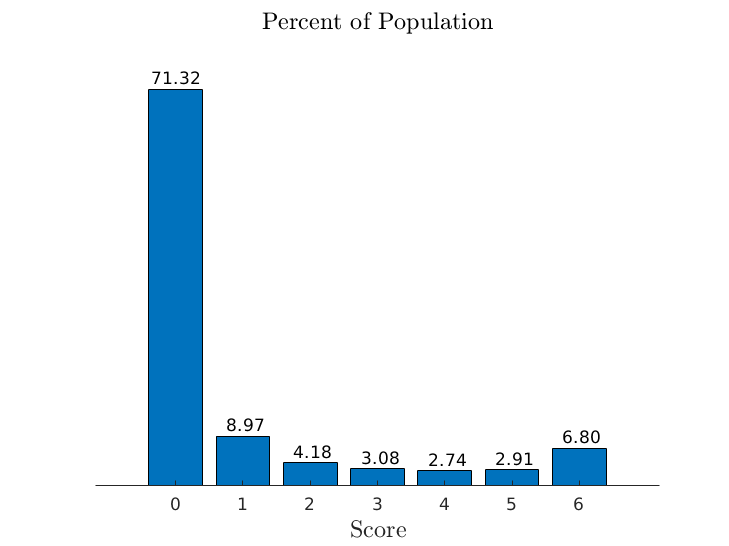

%plot the votes for the total sample

figure
hs=histcounts(tally6)./ngal*100;

bar(0:6,hs);
text(0:length(hs)-1,hs,num2str(hs','%0.2f'),'vert','bottom','horiz','center');
box off
ax=gca;
ax.YAxis.Visible='off';

%set(gca,'ytick',[])
xlabelmine('Score');
titlemine('Percent of Population');

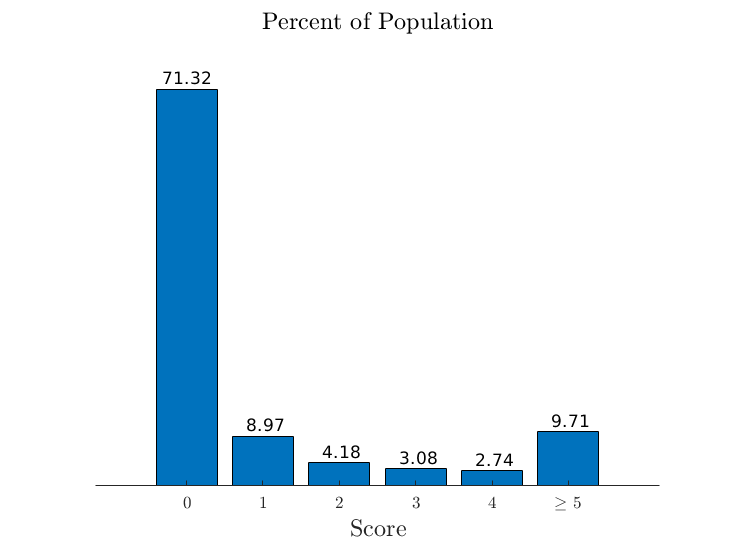


tally5=tally6;
tally5(tally5==6)=5;

figure
hs=histcounts(tally5)./ngal*100;

bar(0:5,hs);
text(0:length(hs)-1,hs,num2str(hs','%0.2f'),'vert','bottom','horiz','center');
box off
ax=gca;
ax.YAxis.Visible='off';
ax.XAxis.TickLabels={'$0$','$1$','$2$','$3$','$4$','$\ge 5$'};
ax.XAxis.TickLabelInterpreter='latex';


%set(gca,'ytick',[])
xlabelmine('Score');
titlemine('Percent of Population');

Let's examine how this would look like if we got rid of one of the classifiers:

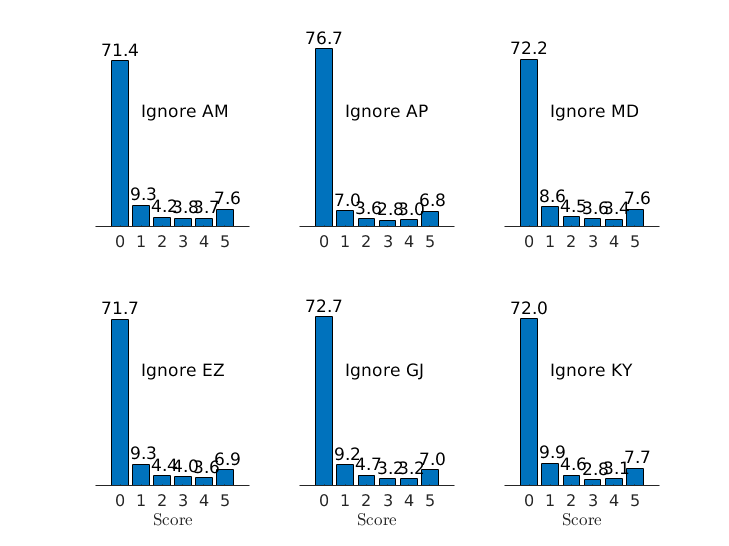

figure

for j=1:length(experts)
    tally=zeros(size(idList));
    
    for i=1:length(experts)
        if i==j
            continue
        end
        
        tally=tally+clsArray.(experts(i)).isJelly;
        
    end
    
    subplot(2,3,j);
    
    hs=histcounts(tally)./ngal*100;
    
    bar(0:5,hs);
    text(0:length(hs)-1,hs,num2str(hs','%0.1f'),'vert','bottom','horiz','center');
    box off
    
    ylim([0 80])
    text(1,50,sprintf('Ignore %s',exTag{j}))
    
    ax=gca;
    ax.YAxis.Visible='off';
    
    
    if j>3
        xlabelmine('Score');
    end
    
    %if mod(j,3)==1
    %ylabelmine(' Percent');
    %end
    %(sprintf('Ignore %s votes',exTag(j)));
    
end

Overall the results change very little if we ignore any one of the classifiers - this has also been seen in the classification consistency table. In the future it may be intersting to compare to non-expert votes.

overall JF fractions are then either ~9% or ~7% depending on whether you require 5 or 6 votes. 

This fraction is lower than for TNG100 - probably because we're probing lower mass hosts. 

## Lets look at score distribution for different redshifts 

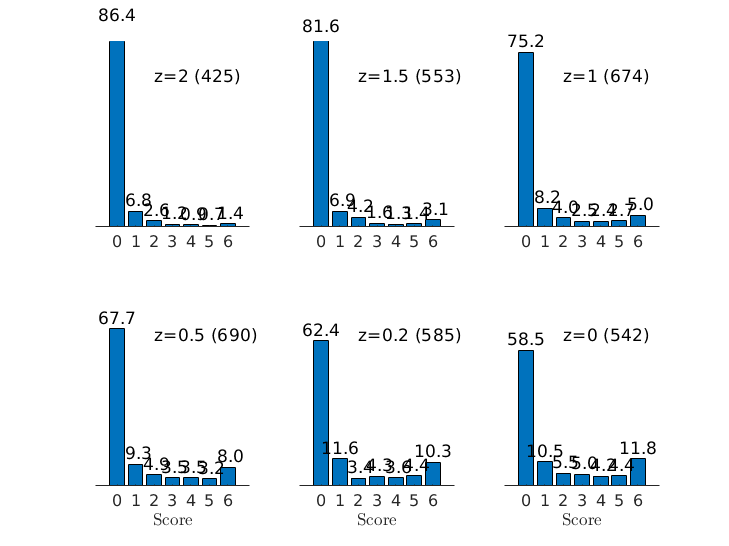

jfFrac=zeros(1,length(snaps));
ng=zeros(size(jfFrac));

for j=1:length(snaps)
    
    snap=snaps(j);
    
    %find the objectsin the right snapshot
    inds=find(objectTable.snap==snap);
    
    
    tally=zeros(size(inds));
    
    for i=1:length(experts)
        tally=tally+clsArray.(experts(i)).isJelly(inds);
        
    end
    
    
    
    subplot(2,3,j);
    hc=histcounts(tally);
    hs=hc./length(inds)*100;
    ng(j)=sum(hc(end-1:end));
    
    bar(0:6,hs);
    text(0:length(hs)-1,hs,num2str(hs','%0.1f'),'vert','bottom','horiz','center');
    box off
    ylim([0 80])
    text(2,65,sprintf('z=%s (%i)',num2str(zreds(j)),length(inds)));
    
    ax=gca;
    ax.YAxis.Visible='off';
    
    
    if j>3
        xlabelmine('Score');
    end
    
    jfFrac(j)=sum(hs(end-1:end))./sum(hs);
    
end

There is a clear trend with redshift for the entire sample. Lets define JF as score 5 and above. the JF fraction vs. redshift is then: 

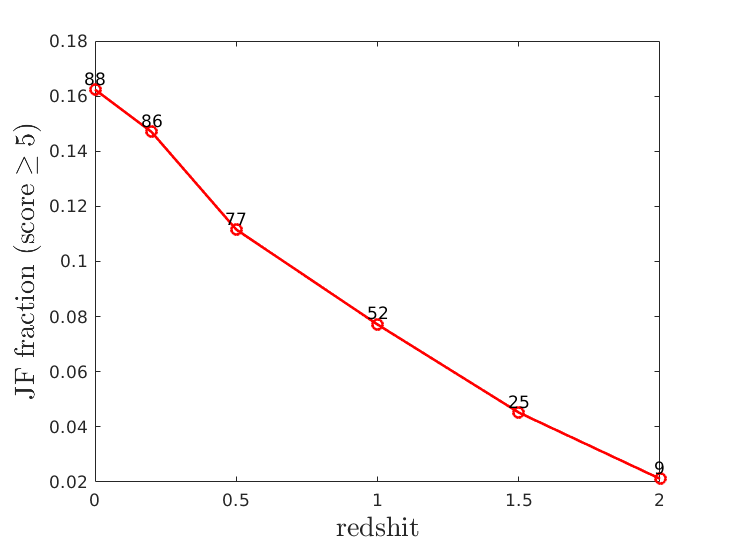



% plot jf fractions vs. redshift 
figure 

plot(zreds,jfFrac,'r-o','LineWidth',1.5)
for i=1:length(snaps)
text(zreds(i),jfFrac(i),num2str(ng(i)) ,'vert','bottom','horiz','center');
end
xlabelmine('redshit',16);
ylabelmine('JF fraction $(\mathrm{score}\ge 5)$',16);

In Yun+2019 the redhsift dependence was flat for identical halo mass - here things are different ! 